# Meta Adaptive Controller Data Analysis

**Author: Fredi R. Mino**

**Date: 2022-12-06**

This notebook shows the performance metrics of the data collected in Feedback Decode

## Dependencies

To run this script, you need the following functions and classes in your workspace:

- `Subject.m`

- `readKDF.m`

- `getRMSE.m`

## Load Subject Data

"D:\FRM\meta-co_adaptive-learning\data";
p1 = Participant(   "01", ...
                    "Stroke; MAS = [3F 1W]", ...
                    "..\data\s-01\task-data-dom.kdf", ...

No such file or directory


Error using fread
Invalid file identifier. Use fopen to generate a valid file identifier.

Error in read_kdf (line 21)
header = fread(file_id, [5,1], 'single');

Error in Participant (line 21)
            [kinematics, features, targets, kalman,

                    "..\data\s-01\task-data-non-dom.kdf")

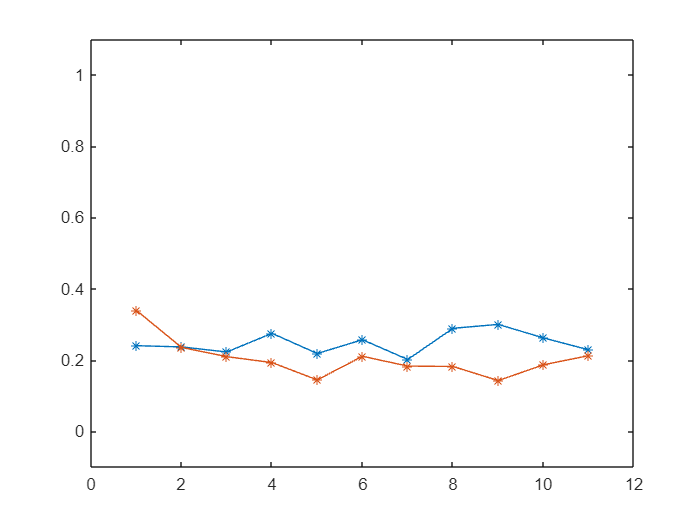

figure
plot(p1.dom_data.rmse, '-*')
hold on
plot(p1.non_dom_data.rmse, '-*')
hold off
ylim([-0.1 1.1])

subj_1 = Subject(1, "Stroke; MAS = [3F 1W]", ...
    "..\data\s-01\task-data-dom.kdf", ...
    "..\data\s-01\task-data-nondom.kdf")

subj_1 =   Subject with properties:

                 ID: 1
          Condition: "Stroke; MAS = [3F 1W]"
       DominantData: "..\data\s-01\task-data-dom.kdf"
    NondominantData: "..\data\s-01\task-data-nondom.kdf"


## Plot Metrics

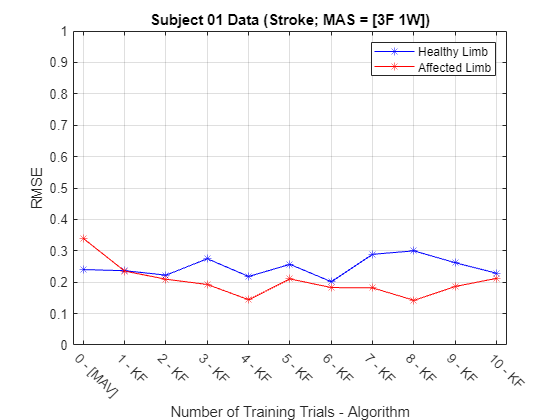

fig_1 = subj_1.plot_rmse();

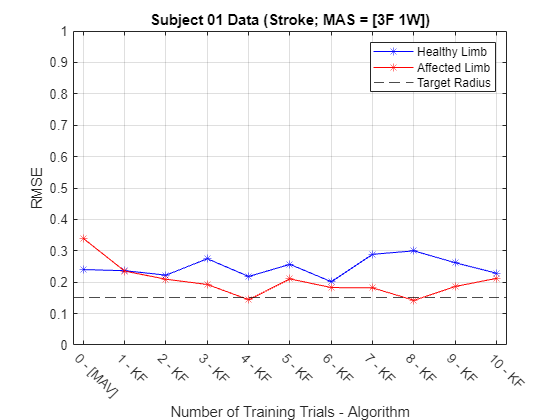

yline(fig_1.CurrentAxes, 0.15, 'k--')
legend(["Healthy Limb","Affected Limb","Target Radius"])

% frm_dom_task_file = "C:\Users\fredi\Box\JAGLAB\Projects\meta-adaptive-controller\data\2022-11-21\fredi-dom\TaskData_20221121-105043.kdf";
% frm_non_dom_task_file = "D:\FeedbackDecode\20221122-160707\TaskData_20221122-160707.kdf";
% cdo_dom_task_file = "C:\Users\fredi\Box\JAGLAB\Projects\meta-adaptive-controller\data\2022-11-21\connor-dom\TaskData_20221121-101521.kdf";
% cdo_non_dom_task_file = "C:\Users\fredi\Box\JAGLAB\Projects\meta-adaptive-controller\data\2022-11-21\connor-non-dom\TaskData_20221121-103441.kdf";

[kinematics, features, targets, kalman, nip] = readKDF("C:\Users\fredi\Box\JAGLAB\Projects\meta-adaptive-controller\data\20221118-120313(pilot)\TaskData_20221118-120313.kdf");

file_healthy = "D:\FeedbackDecode\20221205-094258\TaskData_20221205-094258.kdf"

file_affected = "D:\FeedbackDecode\20221205-104824\TaskData_20221205-104824.kdf"

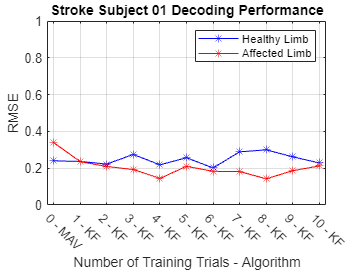

subj_1 =   Subject with properties:

                 ID: 1
          Condition: "Healthy"
       DominantData: "..\data\2022-11-21\fredi-dom\TaskData_20221121-105043.kdf"
    NondominantData: "..\data\2022-11-21\fredi-non-dom\TaskData_20221121-110546.kdf"


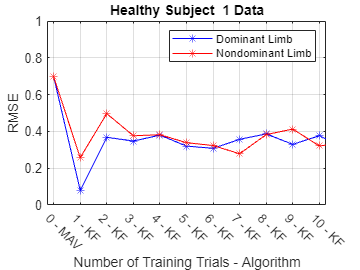

ans =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


subj_2 =   Subject with properties:

                 ID: 1
          Condition: "Stroke"
       DominantData: "D:\FeedbackDecode\20221205-094258\TaskData_20221205-094258.kdf"
    NondominantData: "D:\FeedbackDecode\20221205-104824\TaskData_20221205-104824.kdf"


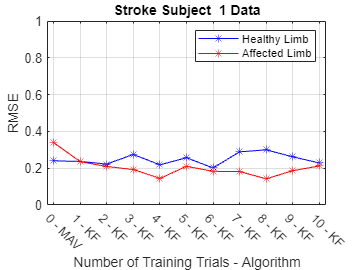

ans =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


[movementRMSEs, xTalkRMSEs] = getRMSE(targets, kalman);

trialRMSEs = movementRMSEs(2:end);
num_blocks = 11;
num_trials = 5;

box_data = zeros(num_trials, num_blocks);
for i=0:num_blocks-1
    if i == 0
        idx_start = 1;
    else
        idx_start = i*num_trials+1;
    end
    idx_stop = idx_start+num_trials-1;
    block_data = trialRMSEs(idx_start:idx_stop);
    adtest(block_data)
    box_data(:,i+1) = block_data';
end

figure()
boxchart(double(box_data))

title("Healthy Subject 02 Non-Dominant 5-Task KF")
xlabel("Trial")
ylabel("RMSE")

[kinematics, features, targets, kalman, nip] = readKDF("C:\Users\fredi\Box\JAGLAB\Projects\meta-adaptive-controller\data\2022-11-17\01_Fredi_10x10_trials\20221117-151117\TaskData_20221117-151117.kdf");
[movementRMSEs, xTalkRMSEs] = getRMSE(targets, kalman);

trialRMSEs = movementRMSEs(end-99:end);
num_blocks = 10;
num_trials = 10;
box_data = zeros(num_trials, num_blocks);
for i=0:num_blocks-1
    if i == 0
        idx_start = 1;
    else
        idx_start = i*num_trials+1;
    end
    idx_stop = idx_start+num_trials-1;
    block_data = trialRMSEs(idx_start:idx_stop);
    adtest(block_data)
    box_data(:,i+1) = block_data';
end

figure()
boxchart(double(box_data))

title("Healthy Subject 01 Non-Dominant 10-Task KF")
xlabel("Trial")
ylabel("RMSE")